Accuracy for User 1: 99.54%


Precision: 0.95


Recall: 1.00


F1 Score: 0.97



Accuracy for User 2: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



Accuracy for User 3: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



Accuracy for User 4: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



Accuracy for User 5: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



Accuracy for User 6: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



Accuracy for User 7: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



Accuracy for User 8: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



Accuracy for User 9: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



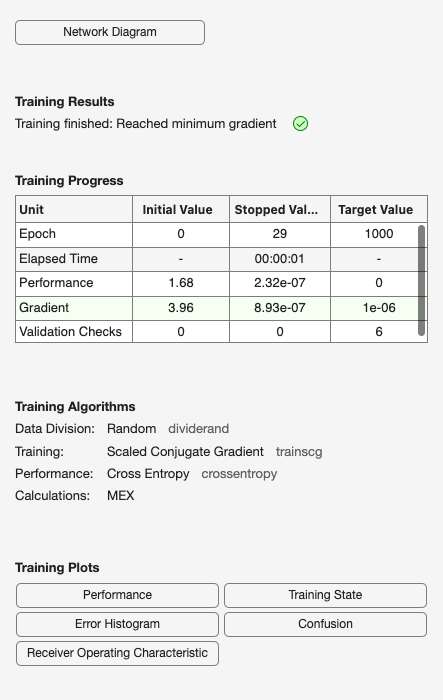

Accuracy for User 10: 100.00%


Precision: 1.00


Recall: 1.00


F1 Score: 1.00



clear all; close all; clc;
% Define constants
dataPath = 'CW-Data/'; % Replace with your actual path
numUsers = 10;
numFilesPerUser = 6;
samplesPerFile = 36;

% Initialize cell array to hold all data
allData = cell(numUsers, numFilesPerUser);

% Load data for each user and each file
for user = 1:numUsers
    for file = 1:numFilesPerUser
        fileName = sprintf('U%02d_Acc_FreqD_FDay.mat', user); % Adjust based on actual file names
        filePath = fullfile(dataPath, fileName);
        loadedData = load(filePath);
        allData{user, file} = loadedData.Acc_FD_Feat_Vec; % Use the correct variable name
    end
end

% Loop through each user to create a binary classifier
for targetUser = 1:numUsers
    X = []; % Feature matrix
    y = []; % Label vector

    % Prepare data for the target user vs. others
    for user = 1:numUsers
        label = (user == targetUser); % 1 if target user, 0 otherwise
        for file = 1:numFilesPerUser
            features = allData{user, file};
            X = [X; features]; % Append features
            y = [y; repmat(label, samplesPerFile, 1)]; % Append labels
        end
    end

    % Scale features
    X = normalize(X);

    % Split data into training and testing sets (80% training, 20% testing)
    cv = cvpartition(size(y, 1), 'HoldOut', 0.2);
    XTrain = X(training(cv), :);
    yTrain = y(training(cv), :);
    XTest = X(test(cv), :);
    yTest = y(test(cv), :);

    % Define ANN architecture
    hiddenLayerSize = 10; % Adjust based on performance (small due to limited data)
    net = patternnet(hiddenLayerSize); % One hidden layer with 10 neurons

    % Configure the ANN for binary classification
    net.performFcn = 'crossentropy'; % Cross-entropy loss for classification

    % Train the ANN
    [net, tr] = train(net, XTrain', yTrain'); % Transpose inputs for ANN format

    % Predict on test data
    yPredProb = net(XTest'); % Get predicted probabilities
    yPred = round(yPredProb'); % Convert probabilities to binary predictions

    % Evaluate model
    accuracy = sum(yPred == yTest) / numel(yTest);
    fprintf('Accuracy for User %d: %.2f%%\n', targetUser, accuracy * 100);

    % Calculate other metrics (precision, recall, F1-score)
    [confMat, ~] = confusionmat(yTest, yPred);
    TP = confMat(2,2);
    TN = confMat(1,1);
    FP = confMat(1,2);
    FN = confMat(2,1);

    precision = TP / (TP + FP);
    recall = TP / (TP + FN);
    f1_score = 2 * (precision * recall) / (precision + recall);

    fprintf('Precision: %.2f\n', precision);
    fprintf('Recall: %.2f\n', recall);
    fprintf('F1 Score: %.2f\n\n', f1_score);
end